clc;
clear all;
% Example data
% 
% [filename, pathname] = uigetfile({'*.csv', 'CSV Files (*.csv)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select a CSV file');
% fullpath = fullfile(pathname, filename);
% data_noload = readtable(fullpath, 'Range', 'A:B'); 


[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_noload = readtable(fullpath, 'Range', 'A:M'); 
 dataMatrix = table2array(data_noload);

% % Define the color values
% 
% blue = [0 0.4470 0.7410];
% red = [0.8500 0.3250 0.0980];
% green = [0.4660 0.6740 0.1880];  % Example green color
% purple = [0.4940 0.1840 0.5560]; % Example purple color
% orange = [0.9290 0.6940 0.1250]; % Example orange color
% 
% % 
% x = dataMatrix(1:10,1);
% y1 = dataMatrix(1:10,2);
% y2 = dataMatrix(1:10,3);
% y3 = dataMatrix(1:10,4);  
% y4 = dataMatrix(1:10,5);  
% y5 = dataMatrix(1:10,6);
% % x = dataMatrix(1:10,1);
% % y1 = dataMatrix(1:10,2);
% % y2 = dataMatrix(1:10,3);
% % y3 = dataMatrix(1:10,4);
% figure;
% [ax, h1, h2] = plotyy(x, y1, x, y2);
% 
% % Set the current axes to the right y-axis
% axes(ax(2));
% hold on;  % Retain the current plot when adding new plots
% % Plot the new data on the same axes as h2
% h3 = plot(x, y3); % 'g' for green color, change as needed
% h4 = plot(x, y4);
% h5 = plot(x, y5);
% hold off;
% % Customizing the plots
% set(h1, 'LineStyle', '-', 'Color', blue, 'LineWidth', 1.5);  % Line style for y1
% set(h2, 'LineStyle', '--', 'Color', red, 'LineWidth', 1.5); % Line style for y2
% set(h3, 'LineStyle', '--', 'Color', green, 'LineWidth', 1.5); % Line style for y2
% set(h4, 'LineStyle', '--', 'Color', purple, 'LineWidth', 1.5); % Line style for y2
% set(h5, 'LineStyle', '--', 'Color', orange, 'LineWidth', 1.5); % Line style for y2
% ylim(ax(2), [0 2]);
% 
% legend([h1, h2, h3, h4, h5], 'Is', 'Is_{13}', 'Is_{11}', 'Is_7', 'Is_5');  % Places the legend outside the plot to the right
% set(legend, 'FontSize', 12);
% ylabel(ax(1), 'Is (A)');
% ylabel(ax(2), 'Is_h (A)');
% xlabel('Effective Air Gap Length');
%     set(gca, 'FontSize', 17);
%     set(gca, 'LineWidth', 1.5);
% title('')
% grid on;
% Define the color values
% Define the color values
blue = [0 0.4470 0.7410];
red = [0.8500 0.3250 0.0980];
green = [0.4660 0.6740 0.1880];  % Example green color
purple = [0.4940 0.1840 0.5560]; % Example purple color
orange = [0.9290 0.6940 0.1250]; % Example orange color

% Data
x = dataMatrix(1:10,1);
y1 = dataMatrix(1:10,2);
y2 = dataMatrix(1:10,3);
y3 = dataMatrix(1:10,4);  
y4 = dataMatrix(1:10,5);  
y5 = dataMatrix(1:10,6);

% Plotting
figure;
[ax, h1, h2] = plotyy(x, y1, x, y2);

% Plot the new data on the same axes as h2
hold(ax(2), 'on'); % Retain the current plot when adding new plots
h3 = plot(ax(2), x, y3, 'LineStyle', '--', 'Color', green, 'LineWidth', 3);
h4 = plot(ax(2), x, y4, 'LineStyle', '--', 'Color', purple, 'LineWidth', 3);
h5 = plot(ax(2), x, y5, 'LineStyle', '--', 'Color', orange, 'LineWidth', 3);

hold(ax(2), 'off');

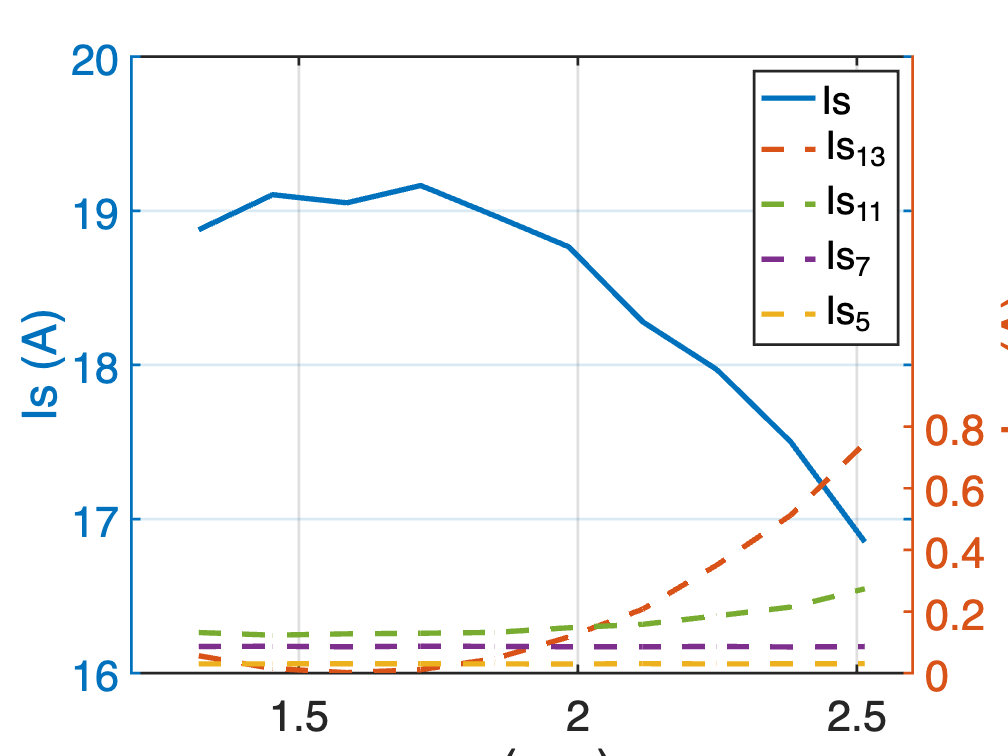


% Customizing the plots
set(h1, 'LineStyle', '-', 'Color', blue, 'LineWidth', 3);
set(h2, 'LineStyle', '--', 'Color', red, 'LineWidth', 3);

% Set y-axis limits for the right y-axis
ylim(ax(2), [0 2]);

% Other plot settings
legend([h1, h2, h3, h4, h5], 'Is', 'Is_{13}', 'Is_{11}', 'Is_7', 'Is_5');
ylabel(ax(1),'Is (A)');
ylabel(ax(2),'Is_h (A)');
xlabel('g_e (mm)');
set(ax, {'FontSize'}, {24; 24});
set(ax, {'LineWidth'}, {1.5; 1.5});
title('');
grid on;

% current_A = dataMatrix(:,2);
% % current_B = dataMatrix(:,3);
% % current_C = dataMatrix(:,4);
% time = dataMatrix(:,1);
% 
% 
% % Torque = dataMatrix(:,2);
% % time = dataMatrix(:,1);
% 
% 
% blue = [0 0.4470 0.7410];
% red = [0.8500 0.3250 0.0980];
% Y = [0.9290 0.6940 0.1250];
% % Plotting
% figure;
% plot(time, current_A , 'Color', blue, 'LineWidth', 1.7);
% % ylim([-200 2000]);
% % hold on;
% % plot(time, current_B, 'Color', red, 'LineWidth', 1);
% % plot(time, current_C, 'Color', Y, 'LineWidth', 1);
% % hold off;
% xlabel('Time (sec)', 'FontSize', 15);
% ylabel('Stator Current (A)', 'FontSize', 15);
% set(gca, 'FontSize', 14);
% set(gca, 'LineWidth', 1.5);
% grid on;
% % lgd = legend('Phase A', 'Phase B', 'Phase C');
% title('Inclined Static Eccentricity');
% % set(lgd, 'FontSize', 14);


% zoomRange = [3, 3.1];
% indexOfInterest = (time > zoomRange(1)) & (time < zoomRange(2));
% 
% % Draw a rectangle to indicate the zoomed area
%  rectangle('Position', [zoomRange(1), -2, zoomRange(2)-zoomRange(1), 4], 'EdgeColor', [0.5 0.5 0.5], 'LineStyle', '--');
% 
% % Create a zoomed-in box
% axes('position', [.60 .55 .25 .18]);
% box on;
% plot(time(indexOfInterest), current_A(indexOfInterest), 'Color', blue, 'LineWidth', 2);
% hold on;
% plot(time(indexOfInterest), current_B(indexOfInterest), 'Color', red, 'LineWidth', 2);
% plot(time(indexOfInterest), current_C(indexOfInterest), 'Color', Y, 'LineWidth', 2);
% ylim([-25, 25]); % Setting the y-axis limits for the zoomed-in region
% axis tight;
% grid on;
% hold off;


